addpath(genpath(pwd))
addpath(genpath('Z:\01_Codes_Projects\Torino_syRe'))

JMAG에서 특정 kW에 대해서 Q값 구하기

해당 d^2L 값 

전류밀도

온도

## Stipetic 코드화 

- Syre와 mcb 코드 최대한 활용하기

### 레퍼런스 값들

값 가져오기

- MotorCAD

- mcb (JMAG)

- JMAG Express (SingleValue)

 mcad=actxserver('motorcad.appautomation');

### Scaling

% scaleMachine              % syRe : Geometry
% devScaleMethodStiepetic   % stipetic 논문에서 수식 발췌 

someSlotArea=842.6/31.04
% From devMBCTeslaSPlaidFromDankai
elecDataMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\MotorLAB_elecdata.mat'
elecData=load(elecDataMatPath)
% SatuMapMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\SatuMap.mat'
SatuMapMatPath='Z:\Simulation\ACCESS2023\SaturationLossMap.mat'
SatuMapData=load(SatuMapMatPath);

%% Scale Coefficient
Factor.k_Axial     =1.2;
Factor.k_Radial    =1.2;
% % k_Winding   =1;

%% Reference MotorCAD 데이터 가져오기
TeslaSPlaidGeometry=tempDefMCADMachineData4Scaling(mcad)

Factor.n_c = 5
Factor.a_p = 3
n_c_ref = double(TeslaSPlaidGeometry.MagTurnsConductor); % turn per Coil
a_p_ref = double(TeslaSPlaidGeometry.ParallelPaths    ); % Parallel Path
Factor.k_Winding = (n_c/a_p)/(n_c_ref / a_p_ref)

[SatuMapTable,SatuMapInfo]=createTableFromMCADSatuMapStr(SatuMapData);
SatuMapTable.CurrentDensityRMS=SatuMapTable.Stator_Current_Line_RMS/someSlotArea
[ScaledMachineData,ScaledSatuMapTable] = devScaleTablebyStiepetic(Factor,SatuMapTable,TeslaSPlaidGeometry);
% Scaled = devScaleMethodStiepetic(Factor,SatuMapData,TeslaSPlaidGeometry)

### DataFormat 변경 

#### SatuaMap2LabLinkFormat (열해석때문에)

%% 
newTable=replaceUnderscoresWithSpace(ScaledSatuMapTable);
newTable = sortrows(newTable,19,"ascend");
WIndex=find(contains(newTable.Properties.VariableUnits,'W')&~strcmp('W',newTable.Properties.VariableUnits))
LossCoefficientCell =newTable.Properties.VariableNames(WIndex)'

LabLinkCell=changeIronLossCell2LabLinkFormat(LossCoefficientCell);
NewTable=replaceTableNamebyCell(newTable,LossCoefficientCell,LabLinkCell);
NewTable=replaceMCADSatuMapTableName2LabLinkName(NewTable);
LabLinkFormatNameCell=defMCADLabLinkFortCell(TeslaSPlaidGeometry)
table4txt=filterAndSortVarTablebyNameCell(NewTable,LabLinkFormatNameCell)
LabLinkTxtPath=fullfile(pwd,'LabLink.txt');
writetable(table4txt,LabLinkTxtPath,'Delimiter','\t')

[~,tyLink]=mcad.GetVariable('ElectroLink_MotorLAB')

% GrossSlotFillFactor_IM1PH 
% RequestedGrossSlotFillFactor 
% 'Motor-CAD EMag'
% 'Ansys'
%'Custom (Advanced)'
mcad.SetVariable('ElectroLink_MotorLAB','Custom (Advanced)');
mcad.SetVariable('Armature_Winding_Definition',2); 
mcad.SetVariable('RequestedGrossSlotFillFactor',TeslaSPlaidGeometry.GrossSlotFillFactor);
mcad.SetVariable('GeometryParameterisation',1);
mcad.SetVariable('RotorDuctType',0);
mcad.SetVariable('n2ac_MotorLAB',2000);
mcad.SetVariable('AcLossFreq_MotorLAB',2);
mcad.SetVariable('MagLossCoeff_MotorLAB',2);
mcad.SetVariable('FEALossMap_RefSpeed_Lab',2000);
mcad.SetVariable('BandingLossCoefficient_Lab',2);
setMcadVariable(ScaledMachineData,mcad);
setMcadVariable(SatuMapInfo,mcad);


#### 변경된 Satu/Loss Map 넣고


mcad.ClearModelBuild_Lab()
mcad.LoadExternalModel_Lab(LabLinkTxtPath);

[~,MotFilePath]=mcad.GetVariable('CurrentMotFilePath_MotorLAB')
[a,b,c]=fileparts(MotFilePath)
ScaleMotFilePath=[a,strrep(b,'Ref','Scaled'),c]

mcad.SaveToFile(ScaleMotFilePath)



#### [TB]SatuMap 2 syre Format

#### [TB]syreMMM2LabLink

### [TB] 특성 비교(TN 계산 !! -> 효율맵) 

방법론별

- Dankai 복습 -Gaussian Model -devMBCFromDankai.mlx 참조

- 테이블로 만들어서 Filter 걸기 (Physics 모델)

- SyRe 코드

데이터소스별 

- Express (1point와 여러포인트 확장)

- MotorCAD

최종목표

- D^2L과 TRV 등 사이징 함수 비교

- Q와 관련된 사이징 - 얘기 어디서? syre 1번 , mmm에는 있나?

                - > 이면에 있는 논의 찾기 syRE    : very simple LPTN으로 

- Scaling Method와 DSE Method 비교 : 

evil is in Detail. Quantization in System Level 시각 

#### 테이블로 만들어서 Filter 걸기!

%Flux 
tempPlotMCADFluxMap(Scaled);
tempPlotMCADFluxMap(MotorCADFEA);

#### 토크 방정식

% MotorCADFEA=createTorqueDqMap(MotorCADFEA,Input);
%Torque
tempPlotMCADTorqueMap(Scaled,Input);
tempPlotMCADTorqueMap(MotorCADFEA,Input);



#### [TB]전압방정식

% Vds_t = Input.Rs*i_d - Wr*Lamda_qs;
% Vqs_t = Input.Rs*i_q + Wr*Lamda_ds;
% Vabs_s = sqrt(Vds_t.^2 + Vqs_t.^2);


#### [WIP]SyRe Code

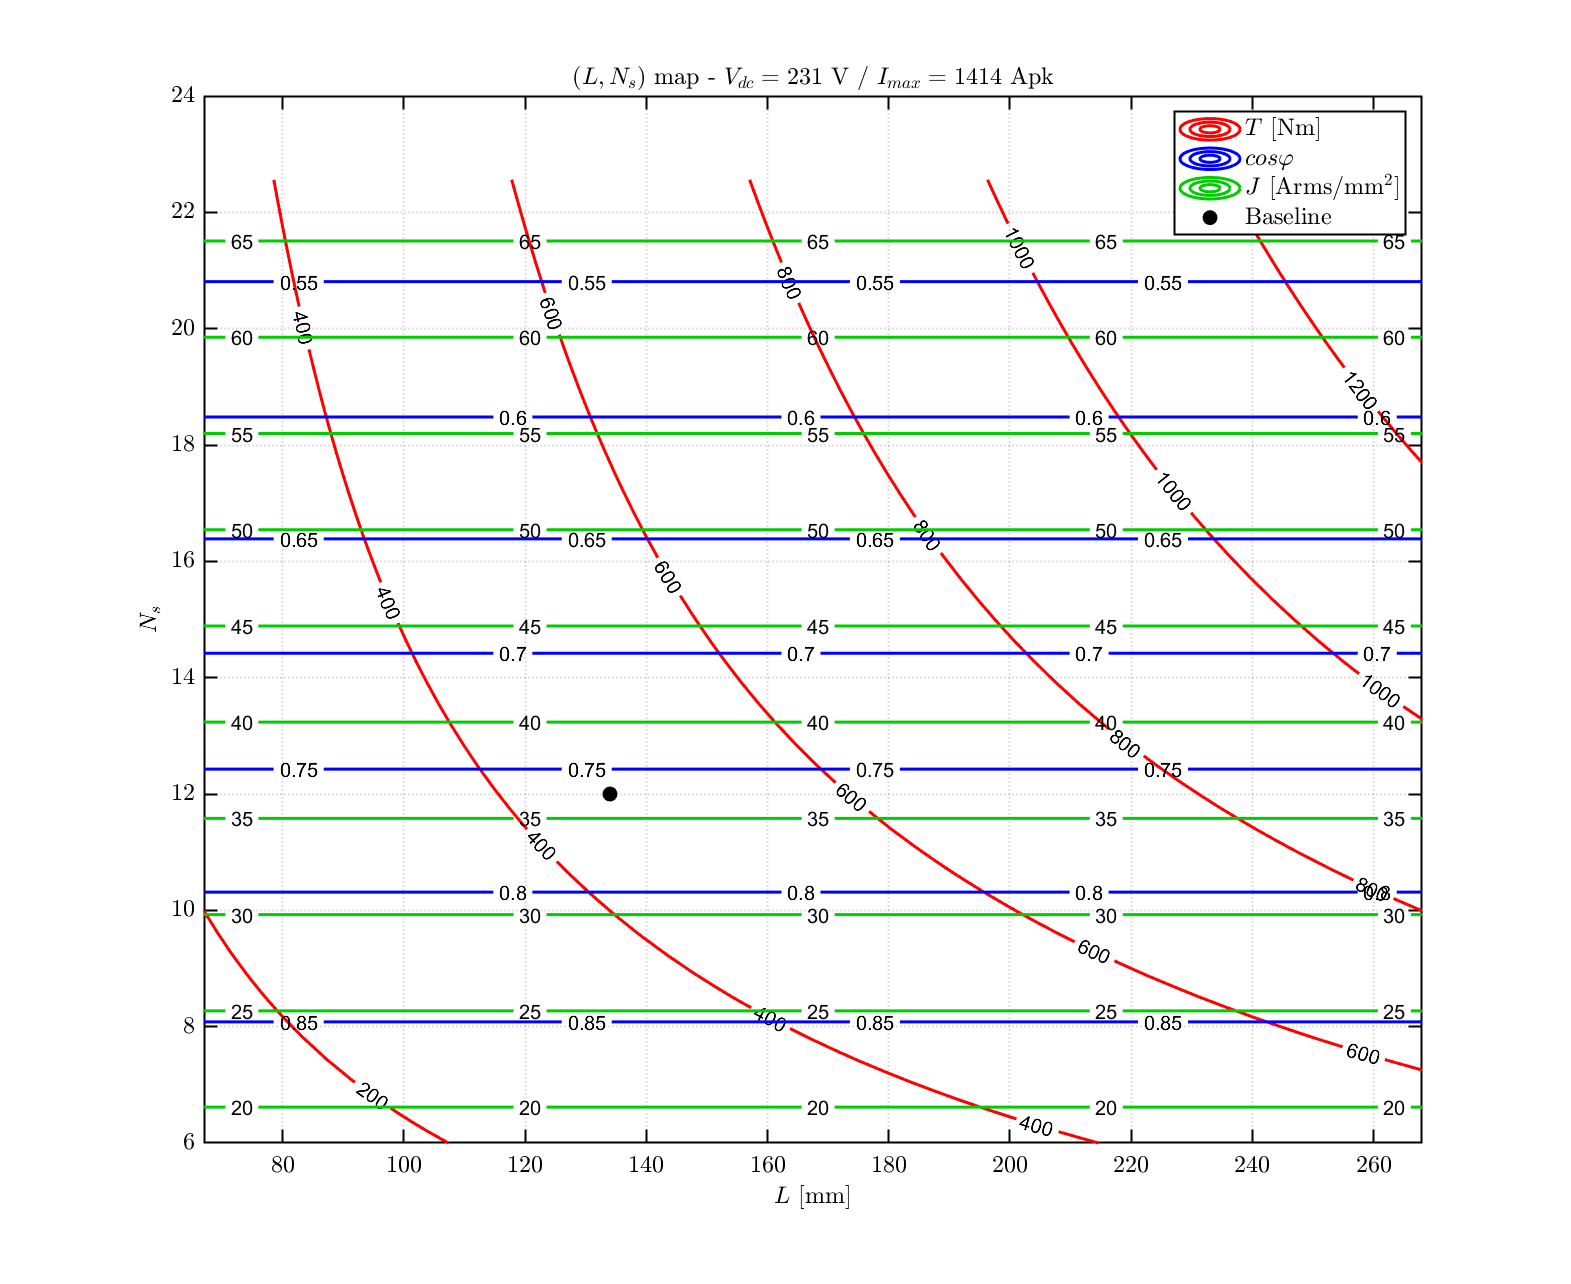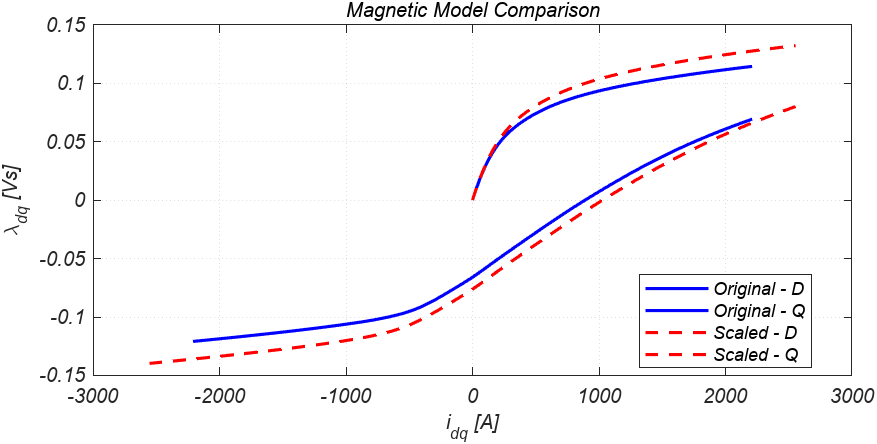

% load dq Map

% Model Scaling  
% Scale Map -> Scale Model 
% Scale Map : 

% Pareto Point From Scaled Model 


Scaled 된 Model의 TN은 비활성화 (Why?

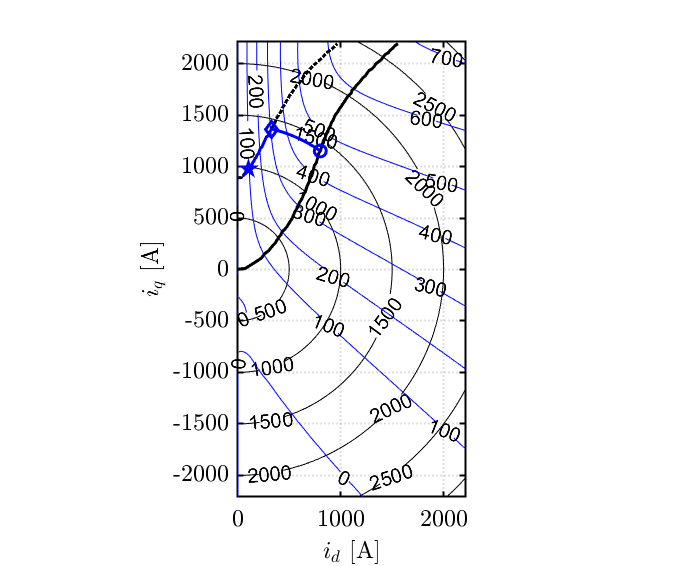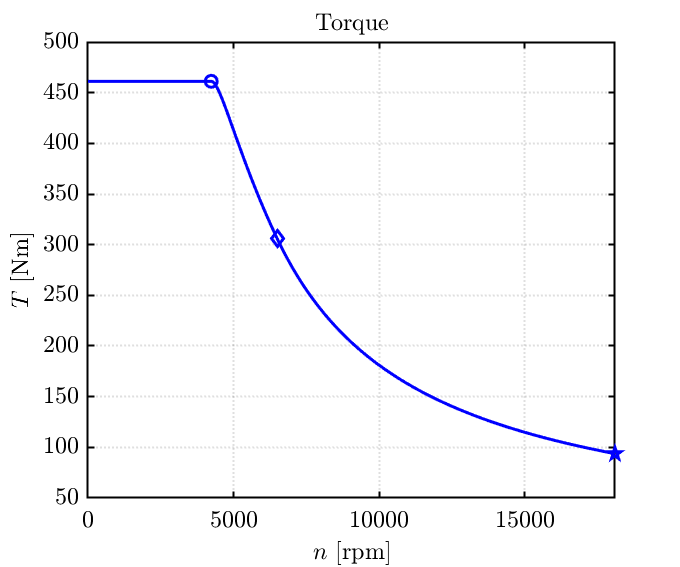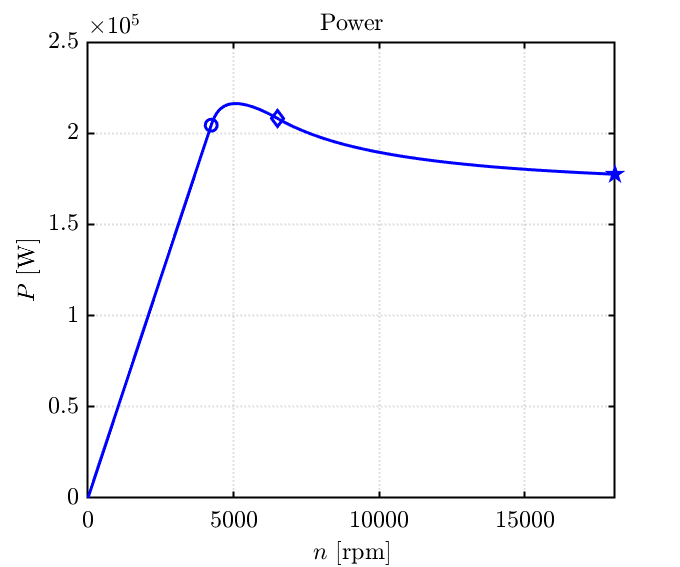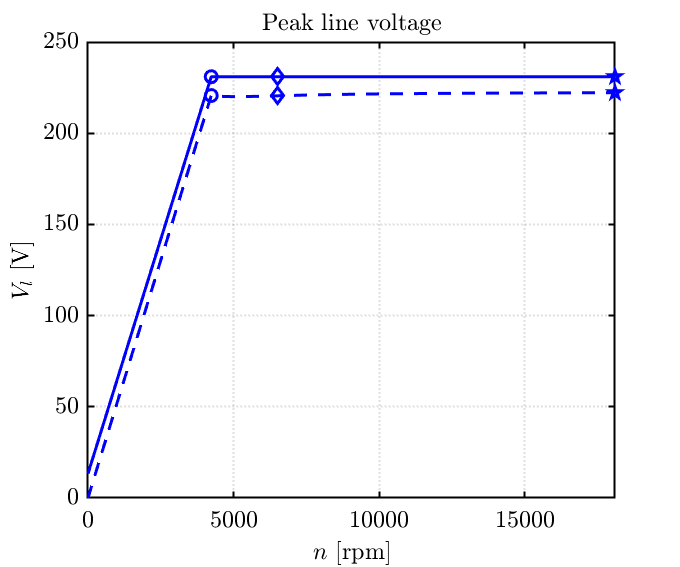

% MotorCAD로 export? 


## 온도 해석

방법들 나열

syre 

- Contant Thermal Kj 확인필요 -> 

- devTransientThermalRise.mlx 참고

devTransientThermalrise4Scaling


## 최적화 - 전압방정식은 제약조건, 효율최대, 원하는 토크와 오차가 최소가 되는 id,iq값찾기

사용법

% Define the objective function to maximize efficiency
objective = @(x) -Efficiency(x);

% Define the nonlinear constraint function for voltage equation
nonlcon = @(x) VoltageEquation(x);

% Initial guess for id and iq
x0 = [0.5, 0.5];

% Define lower and upper bounds for id and iq
lb = [-1, -1];
ub = [1, 1];

% Solve the optimization problem using fmincon
options = optimoptions('fmincon', 'Algorithm', 'sqp');
[x_opt, fval] = fmincon(objective, x0, [], [], [], [], lb, ub, nonlcon, options);

% Display the optimized id and iq values
disp(['Optimized id: ', num2str(x_opt(1))]);
disp(['Optimized iq: ', num2str(x_opt(2))]);
disp(['Maximum Efficiency: ', num2str(-fval)]);


function efficiency = Efficiency(x)
    % Define your efficiency calculation here based on id and iq
    % For example: efficiency = some_function(x(1), x(2));
end

function voltage_eq = VoltageEquation(x)
    % Define the voltage equation as a constraint
    % For example: voltage_eq = some_equation(x(1), x(2)) - V_ref;
end
